# PRÁCTICA 8: CARACTERÍSTICAS LOCALES DE LA IMAGEN (2º PARTE)

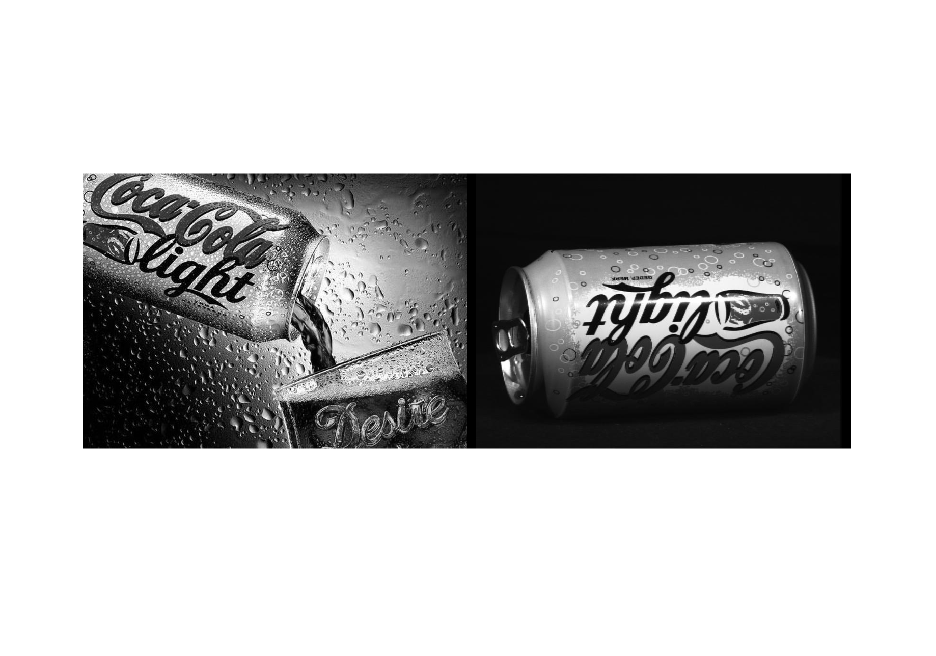

% Cargamos las imágenes que utilizaremos en la sesión práctica

cocacola_lata_1 = imread("coca_cola_1.jpg");
cocacola_lata_2 = imread("coca_cola_2.jpg");
frame1 = imread("Frame 1.tif");

% Pasamos las imagenes a escala de grises (para una mejor detección de las
% características

cocacola_lata_1 = rgb2gray(cocacola_lata_1);
cocacola_lata_2 = rgb2gray(cocacola_lata_2);

montage({cocacola_lata_1,cocacola_lata_2})

## Características tipo SIFT

% Comando
caracteristicas_sift_lata_2 = detectSIFTFeatures(cocacola_lata_2)

caracteristicas_sift_lata_2 =   743×1 SIFTPoints array with properties:

          Scale: [743×1 single]
    Orientation: [743×1 single]
         Octave: [743×1 int32]
          Layer: [743×1 int32]
       Location: [743×2 single]
         Metric: [743×1 single]
          Count: 743


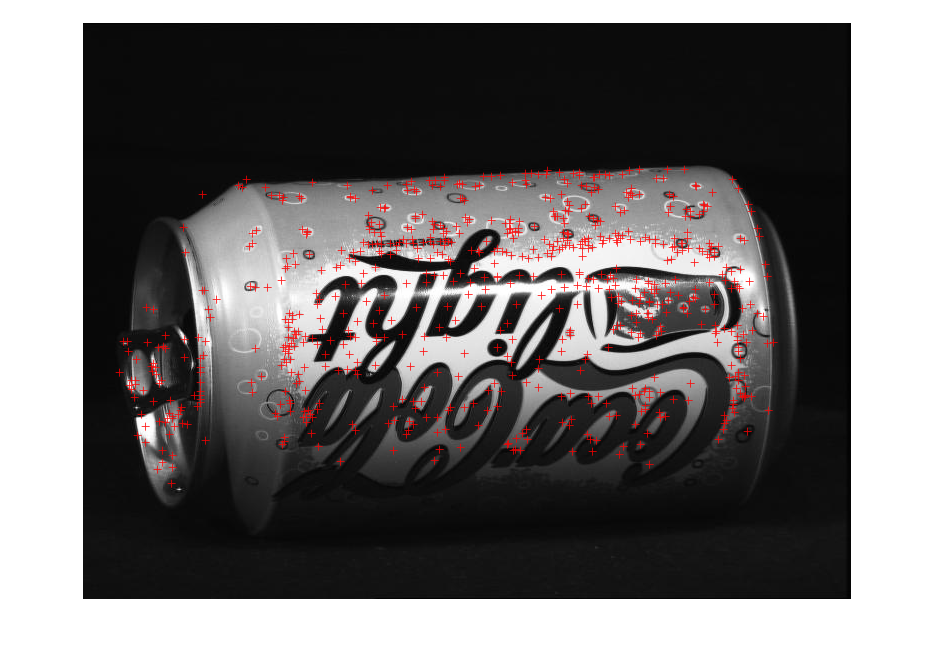

puntos_sift_lata_2 = caracteristicas_sift_lata_2.Location;

imshow(cocacola_lata_2)
hold on
plot(puntos_sift_lata_2(:,1),puntos_sift_lata_2(:,2),'+',Color='r')
hold off


% Analisis de los parámetros de entrada (threshold para los maximos y los
% minimos, threshold para las rectas, número de capas en las octavas y
% valor inicial del sigma).

% Otro ejemplo

caracteristicas_sift_frame_1 = detectSIFTFeatures(frame1)

caracteristicas_sift_frame_1 =   1121×1 SIFTPoints array with properties:

          Scale: [1121×1 single]
    Orientation: [1121×1 single]
         Octave: [1121×1 int32]
          Layer: [1121×1 int32]
       Location: [1121×2 single]
         Metric: [1121×1 single]
          Count: 1121


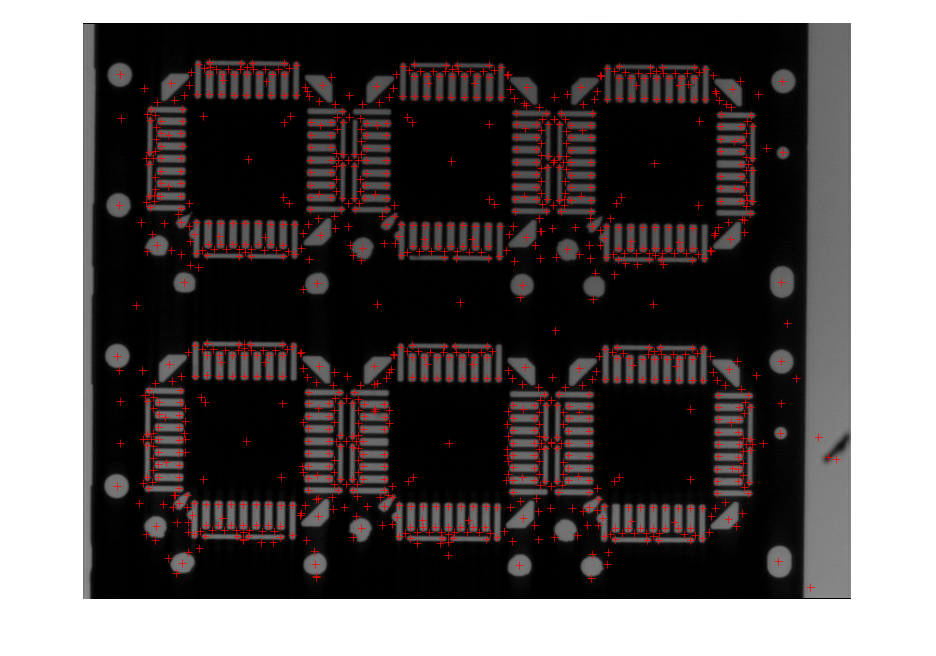

puntos_sift_frame_1 = caracteristicas_sift_frame_1 .Location;

imshow(frame1)
hold on
plot(puntos_sift_frame_1(:,1),puntos_sift_frame_1(:,2),'+',Color='r')
hold off

## Características tipo FAST

% Comando

caracteristicas_fast_lata_2 = detectFASTFeatures(cocacola_lata_2)

caracteristicas_fast_lata_2 =   441×1 cornerPoints array with properties:

    Location: [441×2 single]
      Metric: [441×1 single]
       Count: 441


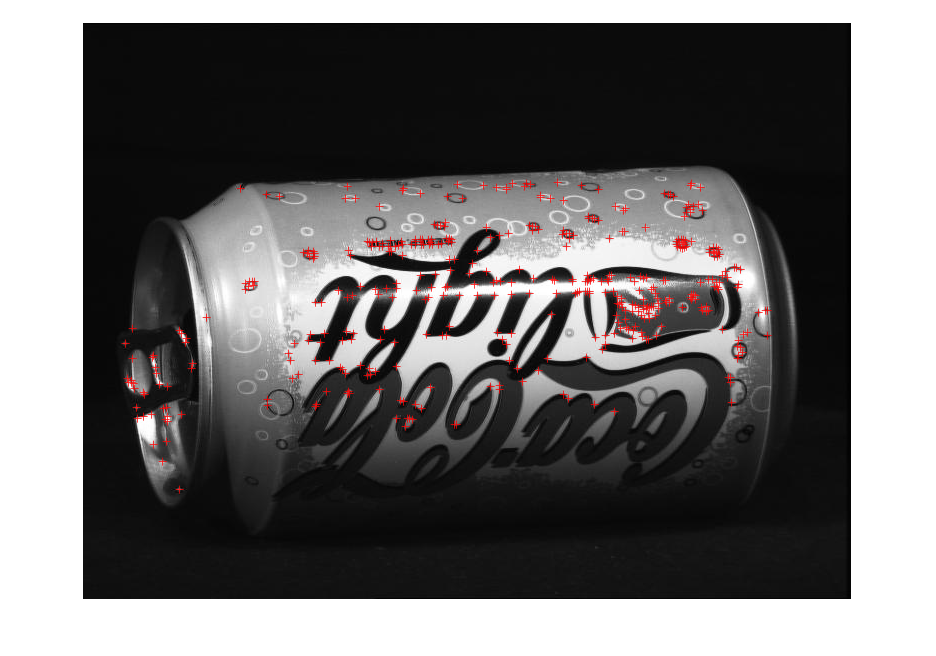


puntos_fast_lata_2 = caracteristicas_fast_lata_2.Location;

imshow(cocacola_lata_2)
hold on
plot(puntos_fast_lata_2(:,1),puntos_fast_lata_2(:,2),'+',Color='r')
hold off

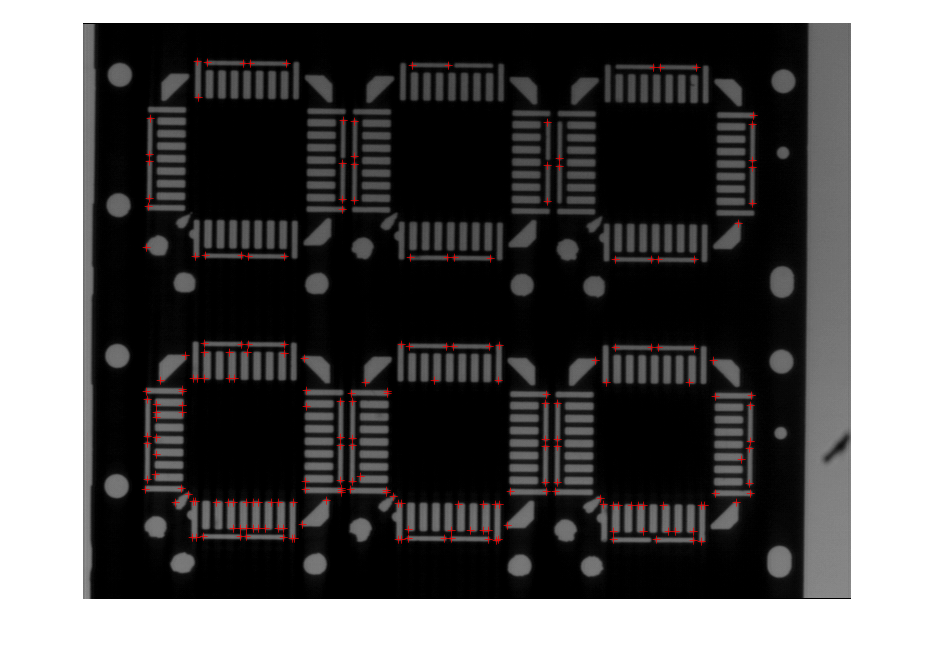

% Otro ejemplo
caracteristicas_fast_frame1 = detectFASTFeatures(frame1);

puntos_fast_frame1 = caracteristicas_fast_frame1.Location;


imshow(frame1)
hold on
plot(puntos_fast_frame1(:,1),puntos_fast_frame1(:,2),'+',Color='r')
hold off

## Características tipo ORB

% Comando

caracteristicas_orb_lata_2 = detectORBFeatures(cocacola_lata_2)

caracteristicas_orb_lata_2 =   5878×1 ORBPoints array with properties:

       Location: [5878×2 single]
         Metric: [5878×1 single]
          Count: 5878
          Scale: [5878×1 single]
    Orientation: [5878×1 single]


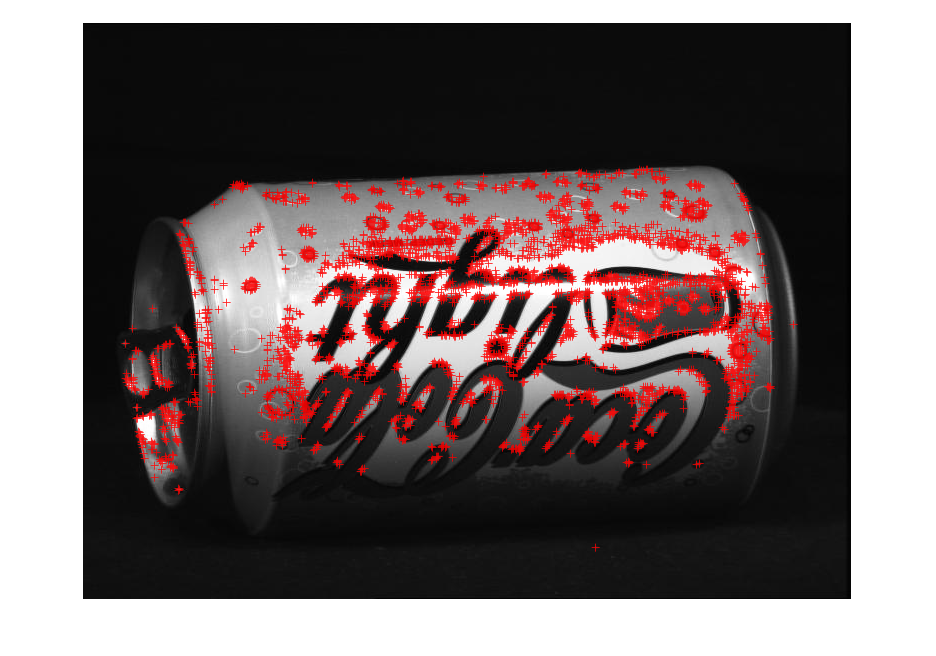

puntos_orb_lata_2 = caracteristicas_orb_lata_2.Location;

imshow(cocacola_lata_2)
hold on
plot(puntos_orb_lata_2(:,1),puntos_orb_lata_2(:,2),'+',Color='r')
hold off

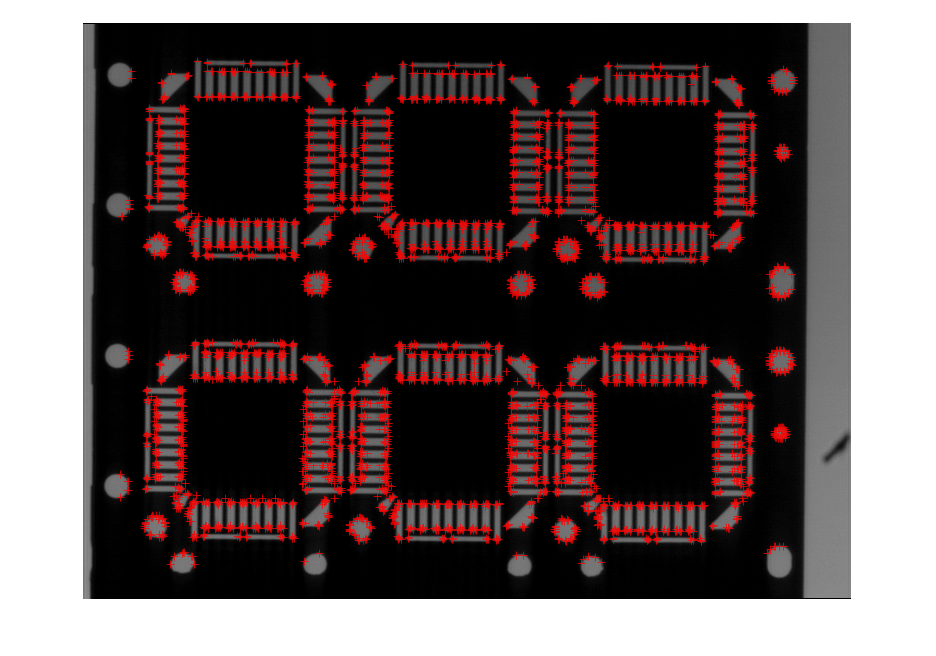

% Analisis de los parámetros de entrada (factor de escala para la mejora
% de la parte FAST del algoritmo, número de octavas y una región de interes
% por si se quieren detectar las características en una subregión de la 
% imagen original.

% Otro ejemplo
caracteristicas_orb_frame1 = detectORBFeatures(frame1);
puntos_orb_frame1= caracteristicas_orb_frame1.Location;

imshow(frame1)
hold on
plot(puntos_orb_frame1(:,1),puntos_orb_frame1(:,2),'+',Color='r')
hold off

## Extraer las caracteristicas de un cierto tipo y compararlas

% extractFeatures permite extraer el descriptor de las caracteristicas
% introducidos como argumento.

[descriptor_sift_lata_2,caracteristicas_sift_lata_2] = extractFeatures(cocacola_lata_2,caracteristicas_sift_lata_2);

[descriptor_orb_lata_2,caracteristicas_orb_lata_2] = extractFeatures(cocacola_lata_2,caracteristicas_orb_lata_2);

caracteristicas_sift_lata_1 = detectSIFTFeatures(cocacola_lata_1);

[descriptor_sift_lata_1,caracteristicas_sift_lata_1] = extractFeatures(cocacola_lata_1, caracteristicas_sift_lata_1);


[indice_emparejamiento, metrica] = matchFeatures(descriptor_sift_lata_2,descriptor_sift_lata_1,MatchThreshold=5)

indice_emparejamiento = 53×2 uint32 matrix
     71   1231
     83   1231
     97    819
    183    716
    192    771
    193    770
    197    784
    199    810
    203    780
    204    779
    205    736
    209    791
    212    707
    224    752
    239    700


metrica = 53×1 single column vector
    0.1260
    0.1349
    0.1813
    0.1245
    0.0932
    0.0709
    0.1046
    0.1393
    0.1858
    0.1076
    0.0870
    0.1899
    0.0942
    0.1042
    0.0898


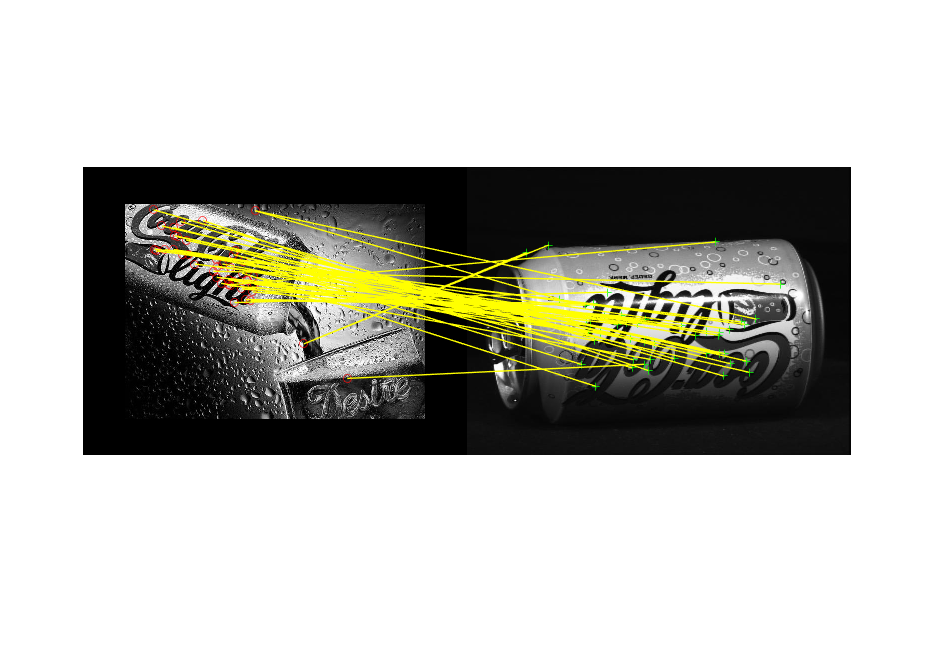


caracteristicas_matcheadas_lata_2 = caracteristicas_sift_lata_2(indice_emparejamiento(:,1),:);
caracteristicas_matcheadas_lata_1 = caracteristicas_sift_lata_1(indice_emparejamiento(:,2),:);
showMatchedFeatures(cocacola_lata_1,cocacola_lata_2,caracteristicas_matcheadas_lata_1,caracteristicas_matcheadas_lata_2,"montage")

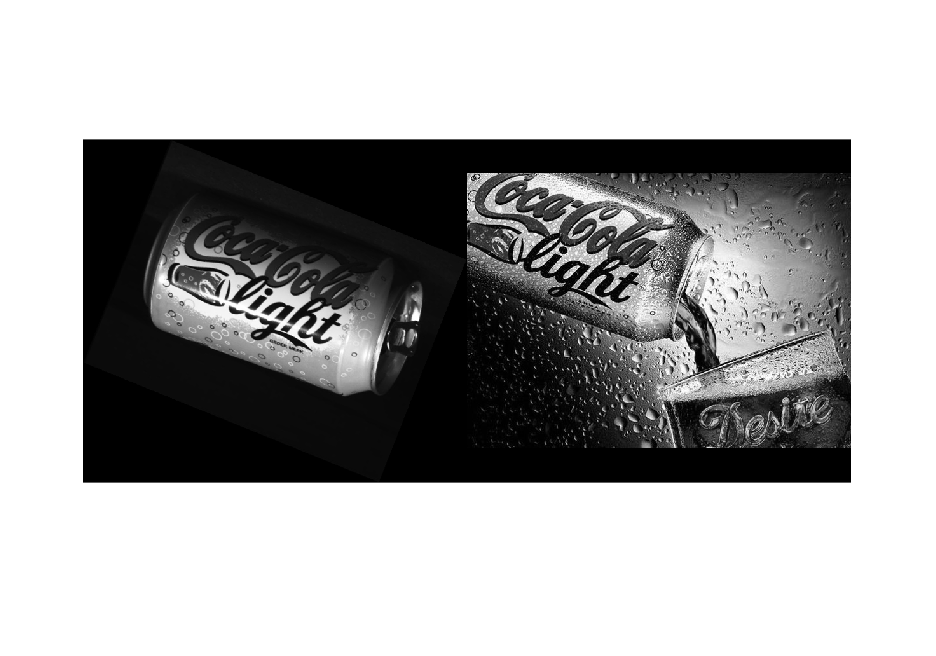

T = estimateGeometricTransform(caracteristicas_matcheadas_lata_2,caracteristicas_matcheadas_lata_1,"affine");
T.T;
cocacola_lata_2_transformada = imwarp(cocacola_lata_2,T);
montage({cocacola_lata_2_transformada,cocacola_lata_1})


% Características SIFT. Analizar los diferentes argumentos de entrada, y el
% vector de características redundante.

% Para comparar objetos entre si, repetimos el proceso con la otra imagen
% conteniendo una lata.

% Comparamos los dos vectores descriptores con el comando matchFeatures

% Mostramos el emparejamiento entre las características

% Veamos cuales son los valores de la métrica para hacernos una idea de
% cuan buena es.

## Ejercicios

% Para las imagenes frame1,frame2 y frame3:

% EJ1. Extrae los descriptores y emparejalos 2 a 2 usando las
% características de tipo SIFT y las de tipo ORB. Cuando muestres el
% emparejamiento, omite el parametro "montage" para ver una visualización
% especialmente apta para estudiar qué transformación permitiría alinear
% una imagen con la otras (cómo calcular dicha transformación lo veremos
% en la próxima sesión práctica).

% Para las imágenes Simbolos, Simbolo_1 y Simbolo_2:

% EJ1. Aunque existen métodos más eficientes, con los comandos vistos
% en esta sesión de prácticas ya es posible definir funciones en Mat-
% lab que, dado un umbral (threshold) T, determinen si dos imágenes
% son iguales o si el objeto presente en una de ellas se encuentra en
% la otra. Implementa una función de este tipo y valida su funcionamien-
% to utilizando las imágenes cocacola_lata_1 y cocacola_lata_2. Valí-
% dalo también con las imágenes Simbolos, Simbolo_1 y Simbolo_2.

% Carpeta QR_codes:

% EJ1. Usando el comando dir, y sabiendo que las imágenes en la carpeta 
% "QR_codes" tienen extensión .png, desarrollar un código o función que:
%   1. Extraiga las características (SIFT o ORB) de todos los códigos QR 
%      contenidos en la carpeta "QR_codes".
%   2. Extraiga las características del código QR de prueba ubicado en la 
%      carpeta principal de imágenes.
%   3. Compare dichas características para identificar a cuál de los códigos 
%      QR de la carpeta "QR_codes" (numerados del 0 al 19) corresponde el 
%      código de prueba, devolviendo el número del código coincidente.
